# Lecture 6

## Power Spectral Density (PSD)

Since we cannot have a mathematical model of random signals, so instead we have a statistical model. 

The top half of figure 13.12 shows us how to compute the autocorrelation of the signal coming out, if we have the autocorrelation of the input signal. 

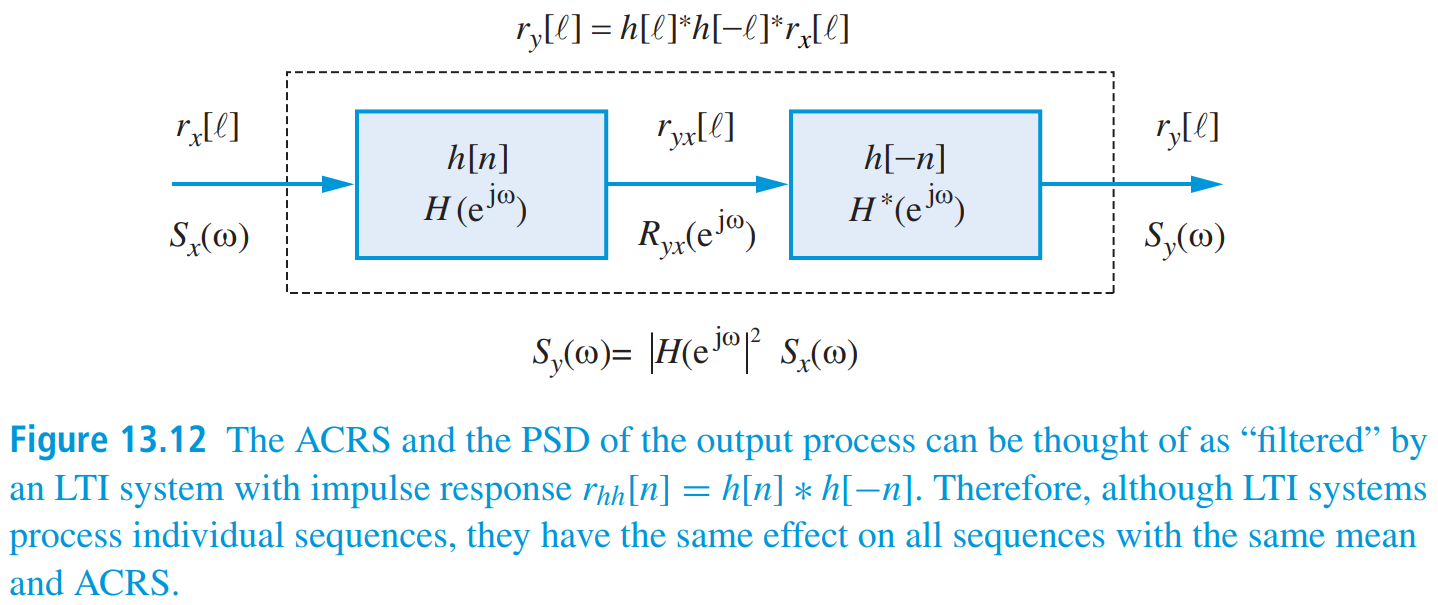

The bottom half of the figure has to do with the power spectral density.

### Definition of PSD

Power spectral density is used to characterise stationary random processes in the frequency domain. Power Spectral Density is defined as follows:

        
$$S_{\mathrm{xx}} \left(\omega \right)=R_{\mathrm{xx}} \left(e^{j\omega } \right)=\sum_{\ell =-\infty }^{\infty } r_{\mathrm{xx}} \left(\ell \right)e^{-\jmath \ell \omega }$$


Essentially, Power Spectral Density is the discrete-time Fourier Transform of the auto-correlation sequence $r_{\mathrm{xx}} \left(\ell \right)$.

**Notice that phases disappear when we compute the spectrum.**

*SIDE NOTE:* If we have a signal with some oscillation, the oscilation is observed in the autocorrelation. Taking the Fourier Transform of the same autocorrelation, we will observe that there is energy at that particular frequency.

We can go the opposite direction. Given the PSD, we can compute the auto-correlation sequence by the inverse Fourier Transform as follows:

        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } S_{\textrm{xx}} \left(\omega \right)e^{\;j\omega \ell } \;\mathrm{d}\omega$$


### Quiz: Compare the PSD of two sinusoids 

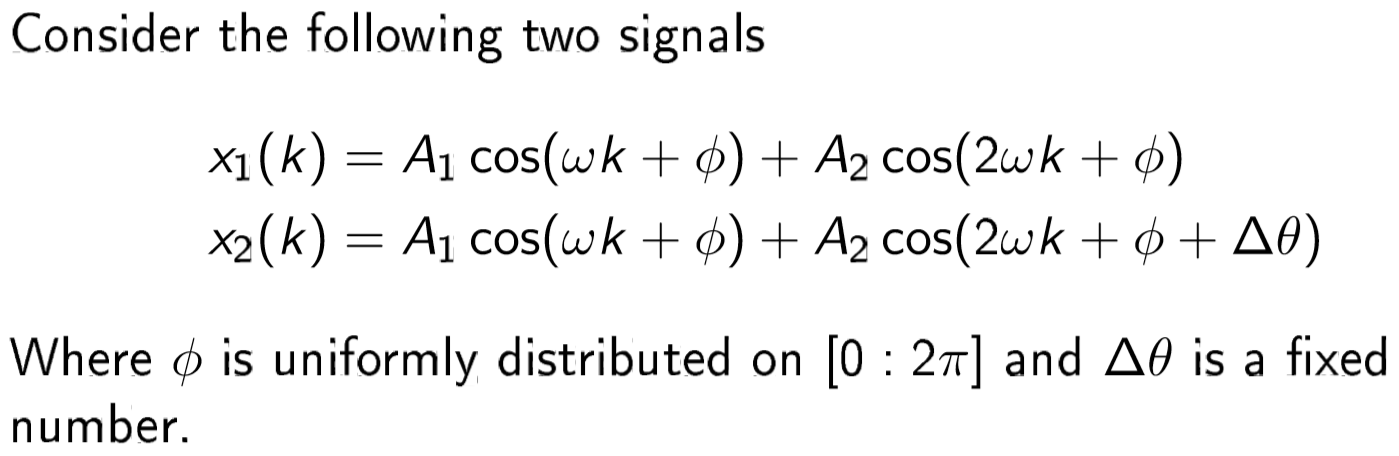

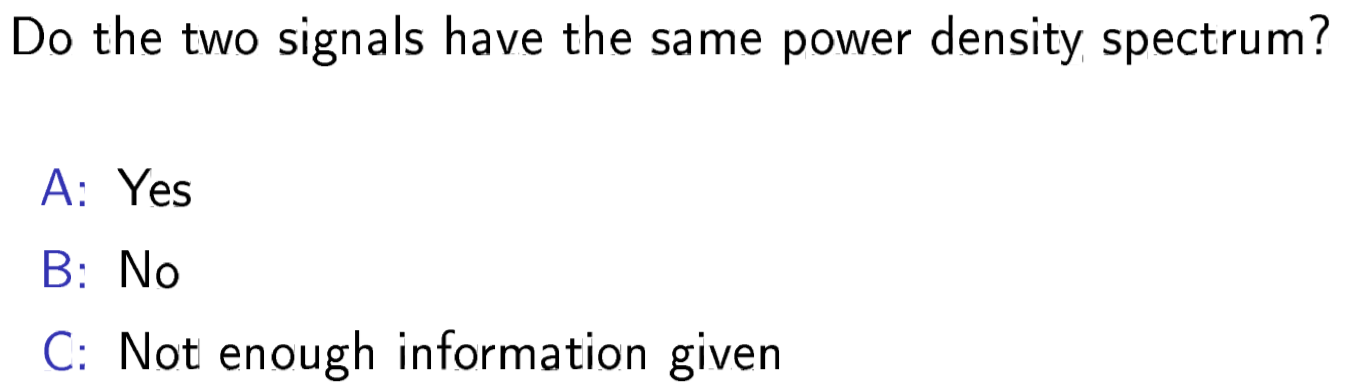

The answer is A; the two signals have the power density spectrum.

In this quiz, we need to compare the PSD of the two signals; $x_1 \left(k\right)$ and $x_2 \left(k\right)$ 

The only difference between the two signals is that $x_2 \left(k\right)$ is a fixed phase shift of $\Delta \theta$

In order to compare compute the PSD, we need to compute the autocorrelation of the signal.

Last week (see problem ADSI Problem 4.4.3) we computed the autocorrelation of a generic real sinusoid $x\left(n\right)=\mathrm{Acos}\left(\omega n+\phi \right)$, which was:

        
$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\cos \left(\omega \ell \right)$$


From this result, we see that the phase does not matter. Therefore, the autocorrelation of $x_1 \left(k\right)$ and $x_2 \left(k\right)$ are the same.

This means that the corresponding PSDs are also the same.

**Lesson: when you compute the PSD, we only know the amount of energy at each given frequency. But we have no clue about the phase, which is essentially lost.**

### Computing PSD of Example Signals

#### White Noise

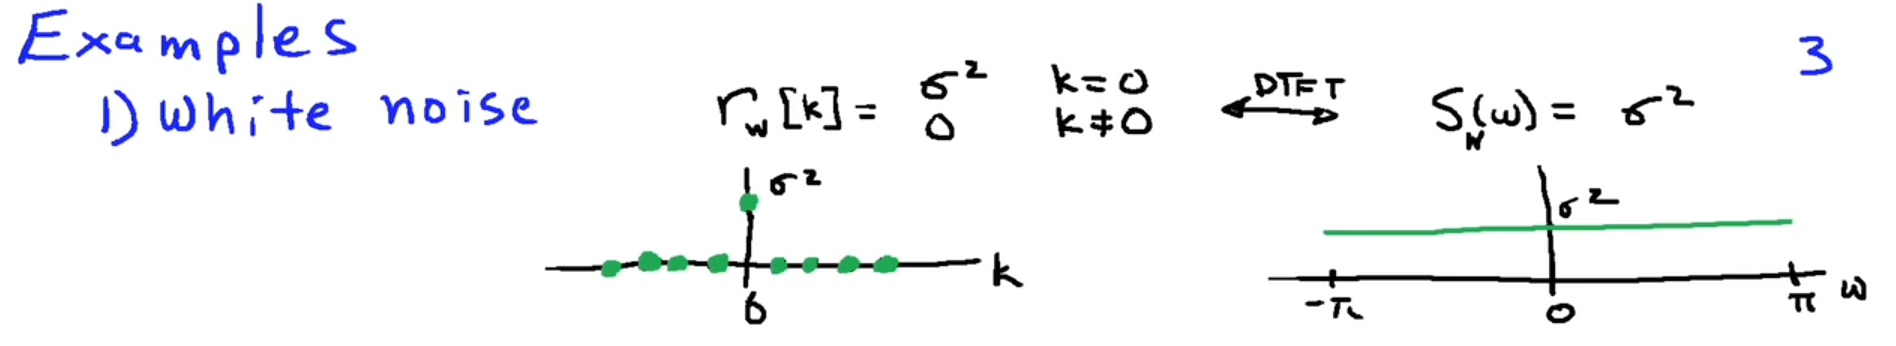

The power spectral density is constant which means that we have the same power across all frequencies. This signal is called white noise because the power is equally distributed across the entire spectrum.

#### Random Sinusoid

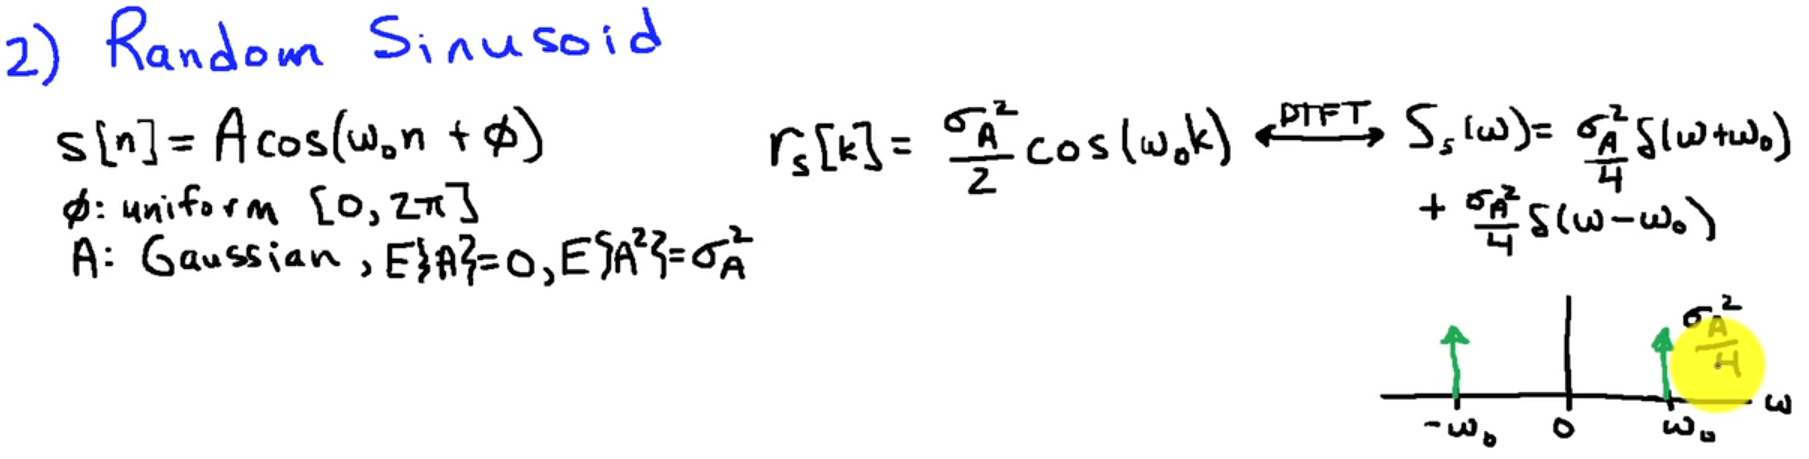

The power spectral density shows that the power is concentrated at $\pm \omega_0$. The area under these concentrations is $\frac{1}{4}\sigma A^2$.

#### Coloured Noise

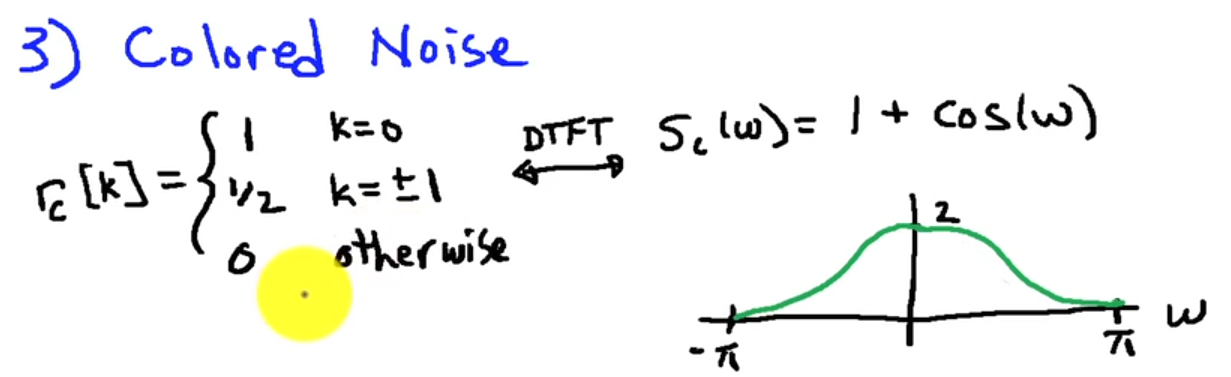

### Average output of a filter

Suppose we want to know the average output of the filter i.e., $E\left\lbrack y^2 \left(n\right)\right\rbrack$

The average output of a filter is actually just the value of the autocorrelation at lag 0. How? We can see this if look at the expression from a different perspective:


$$E\left\lbrack y^2 \left(n\right)\right\rbrack =E\left\lbrack y\left(n\right)y\left(n-0\right)\right\rbrack =r_y \left(0\right)$$


Using the inverse definition of the PSD, we can compute $r_y \left(0\right)$


$$r_y \left(0\right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } S_{\textrm{xx}} \left(\omega \right)e^{\;j\omega \cdot 0} \;\mathrm{d}\omega$$



$$r_y \left(0\right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } S_{\textrm{xx}} \left(\omega \right)\;\mathrm{d}\omega$$


If we integrate the PSD from $-\pi$ to $\pi$, the resulting quantity is equal to the power in the time-domain. This means that **energy in the time-domain is equal to energy in the frequency domain**.

Another perspective:

Let $P_{\mathrm{ab}}$ be a normalised integration of the PSD from the interval $\omega_a$ to $\omega_b$. The quantity $P_{\mathrm{ab}}$ is the expected (or average) contribution to the total power (or variance) that is due to the components of the random process between $\omega_a$ and $\omega_b$. In other words, the area under the curve between  $\omega_a$ and $\omega_b$ is the power that that portion of the spectrum is expected to contribute to the random process. It tells us how power is distrubuted in a frequency spectrum.

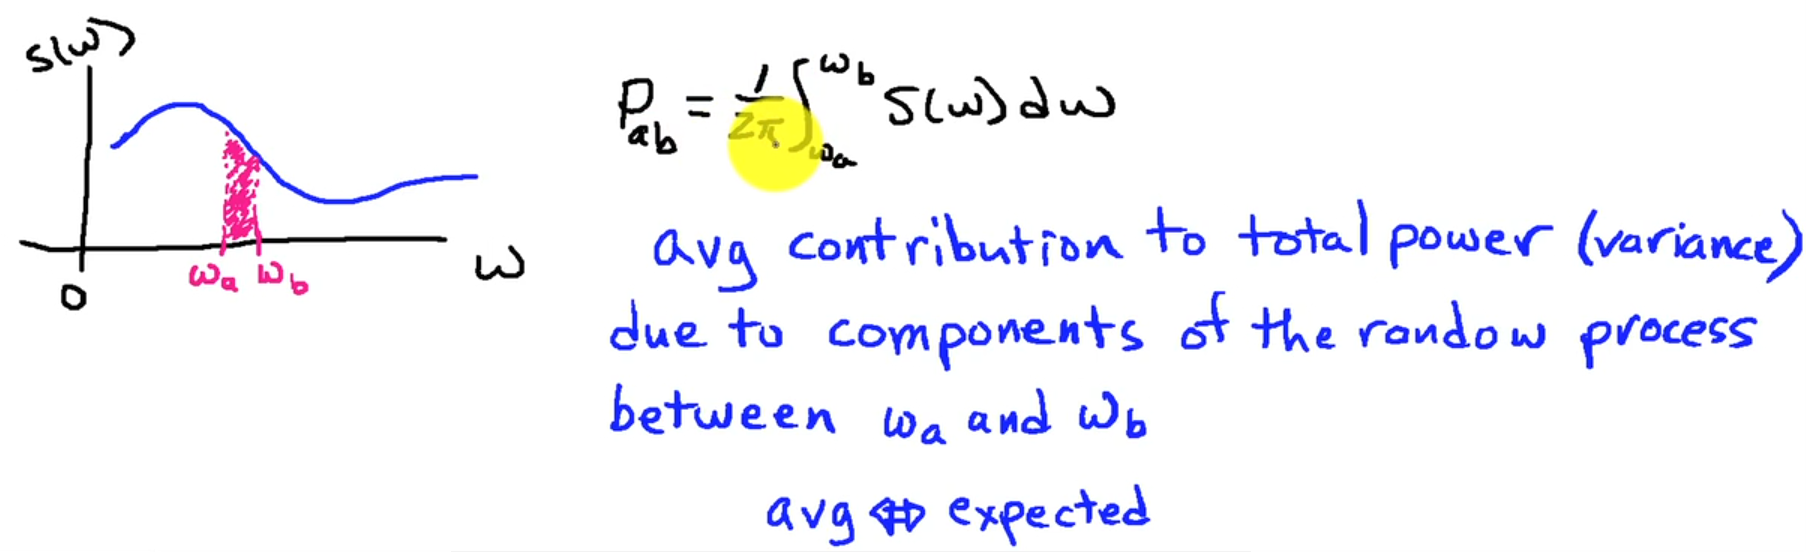

#### Example: Power Spectrum Analyser

Suppose we want to know the power spectrum of some input signal $x\left\lbrack n\right\rbrack$. We can pass that signal to an ideal bandpass filter with very narrow band and compute the power at the output. We define the bandpass filter to have the unit response in the vecinity of $\omega_c$ and the band $\Delta \omega$ is very small. Our bandpass filter rejects frequencies outside $\Delta \omega$ and pass any frequency inside this band.

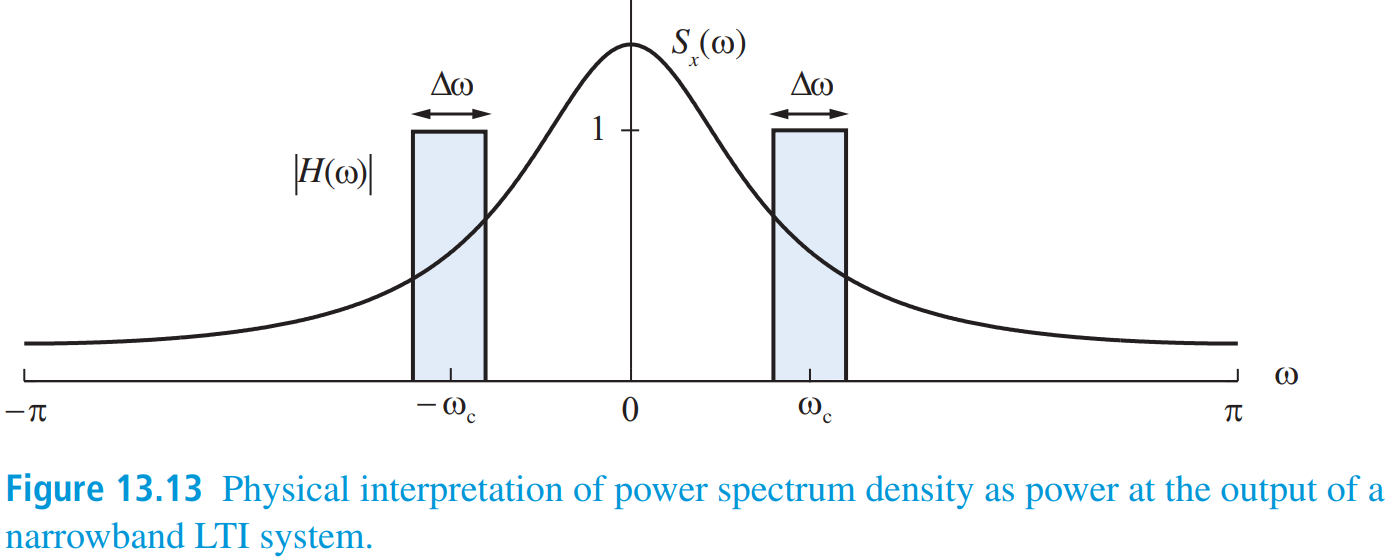

Now, the question is how to do we compute the power spectrum of our ideal narrow bandpass filter when the signal is random?

The answer is to compute the the average output of the filter.

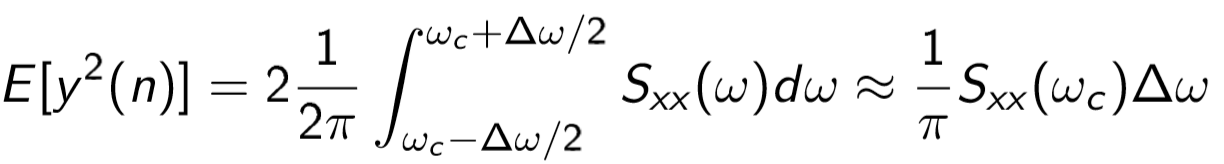

Since the spectrum is symmetic around zero, we get power contribution from both sides of zero. This is called a double-sided spectrum. Therefore, we have $2\frac{1}{2\pi }$ in the equation above.

## Quiz: How do we know if a system in the real-world is linear and time-invariant? 

In this class, we always make the assumptions that our systems are LTI system, but how do we actually know if a real-world system is LTI.

How do we measure if a system is linear and time-invariant?

We can measure if a system is linear by checking the two linearity properties:

    1) $T\left(u+v\right)=T\left(u\right)+T\left(v\right)$

- Feed the system with the sum of two signals $x_1 \left(n\right)+x_2 \left(n\right)$ and observe the output $y\left(n\right)$. 

- Feed the system with $x_1 \left(n\right)$ to record the output $y_1 \left(n\right)$.

- Feed the system with $x_2 \left(n\right)$ to record the output $y_2 \left(n\right)$.

- Now, the output $y\left(n\right)$ should be the same as $y_1 \left(n\right)+y_2 \left(n\right)$

    2) $T\left(A\;v\right)=A\;T\left(v\right)$

- Feed the system with a signal with certain amplitude $A$ e.g. $A=42$. Record the output $y\left(n\right)$

- Feed the system with the same signal but where the amplitude is 1. Record the output $z\left(n\right)$

- The two outputs should have following relations: $y\left(n\right)=42\cdot z\left(n\right)$

We can measure if a system is time-invariant as follows:

- Feed the system with a known signal $x\left(n\right)$ and measure the output $y\left(n\right)$

- Feed the system with the same signal but shifted $x\left(n-k\right)$ the output should also be shifted $y\left(n-k\right)$

A more elegant approach is to compute the coherence function:

        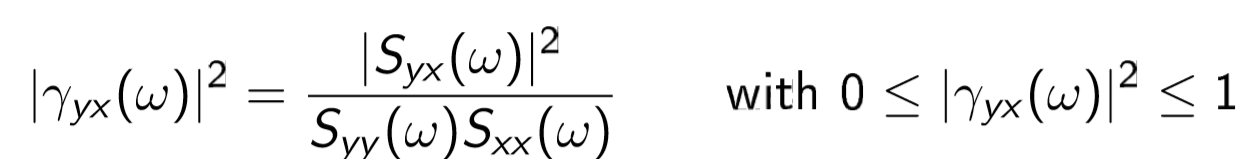

For a linear system, the coherence function should be 1 or very close to it:

        
$${\left|\gamma_{\mathrm{yx}} \left(\omega \right)\right|}^2 =1$$


Before talking about the coherence function, we need to describe the cross power spectrum density.

## Cross Power Spectrum Density

Cross power spectrum density $S_{\mathrm{yx}} \left(\omega \right)$ is the Fourier Transform of the cross-correlation:


$$S_{\textrm{yx}} \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\mathrm{yx}} \left(\ell \right)e^{-j\omega \;\ell }$$


The cross power spectrum compares two signals and computes how much the two signals oscillate in phase. If we get a large value at a given frequency $\omega_0$, then this means the two signals are oscilliting together at $\omega_0$. If $S_{\textrm{yx}} \left(\omega_0 \right)$ is small then the two signal are not in phase at $\omega_0$. 

*Why do we care?* The cross power spectrum density allows us to define a coherence function.

## Coherence Function

The (magnitude squared) coherence function allows us to determine in an elegant way when a system is linear.

Formally, the (magnitude squared) coherence function is defined:

        
$${\left|\gamma_{\mathrm{yx}} \left(\omega \right)\right|}^2 =\frac{{\left|S_{\mathrm{yx}} \left(\omega \right)\right|}^2 }{S_{\mathrm{yy}} \left(\omega \right)S_{\mathrm{xx}} \left(\omega \right)}$$


where $0\le {\left|\gamma_{\mathrm{yx}} \left(\omega \right)\right|}^2 \le 1$i.e., the function yields a number between zero and one.

**The coherence function of a perfect linear system is equal to 1.**

However, in the real-world we don't always get a coherence of 1. 

There are three primal factors that causes the coherence function to fall below 1.

Suppose we want to determine whether a system or a filter is linear:

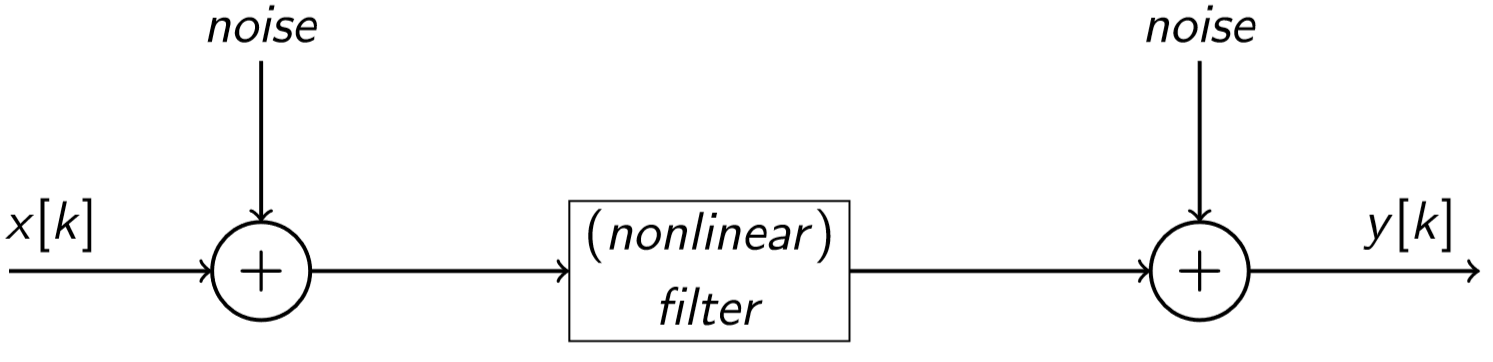

- Factor 1: After we measure $x\left(n\right)$, some unaccounted noise creeps into the signal before going into the system. 

- Factor 2: Some unaccounted noise creeps into the output signal before we measure it.

- Factor 3: The filter contains some nonlinear components.

***Important lesson:*** The coherence function is a tool that we can use to measure whether any given system is actually linear. Since the coherence function measures how close a system is linear, we don't know whether a low coherence is due to noise or a non-linear filter. 

### Coherence Estimates in MATLAB

Let us try it in MATLAB:

#### High-Pass IIR filter

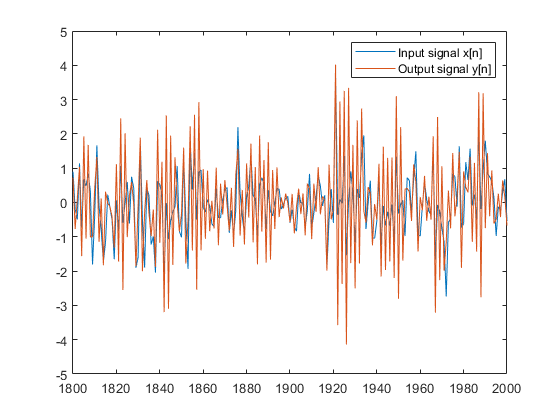

N = 2000;
n = 1800:N;

% Create an input signal of random numbers
x = randn(N, 1);

% Define a high pass IIR filter that attenuates low
% frequencies and amplifies high frequencies
b = 1;
a = [1, 0.8];

y = filter(b, a, x);
plot(n, x(n), n, y(n));
legend('Input signal x[n]', 'Output signal y[n]')

We can plot the magnitude response to see which frequencies the filter is attenuating and which frequency components it is amplifying:

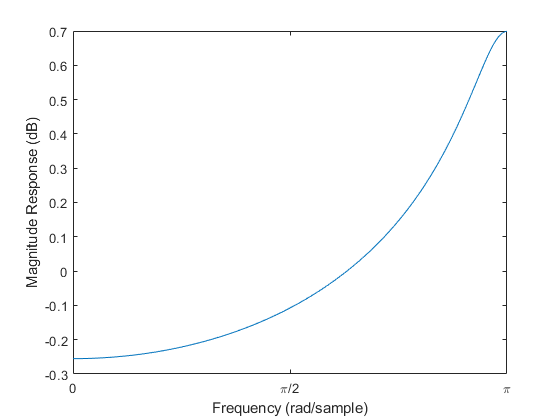

[H, w] = freqz(b, a, 'whole');
plot(w, log10(abs(H)));
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude Response (dB)')
xlim([0, pi]);

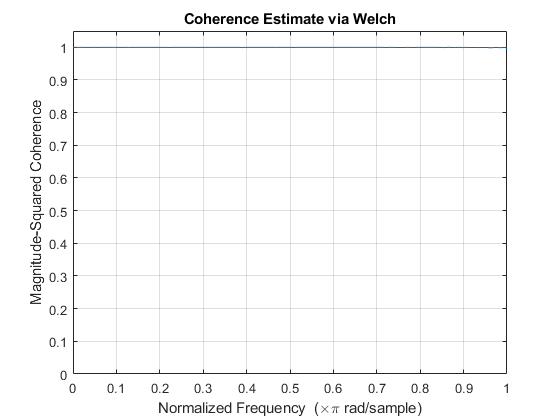

% Compute and plot the coherence estimate
mscohere(y, x);
ylim([0, 1.05]);

Notice that the estimate coherence function is 1. This is not a surprise because we are sending the input signal through a LTI system.

#### High-pass filter with noise at the output

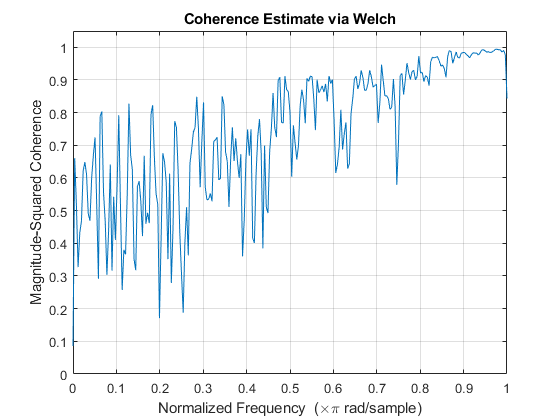

% Define a high pass IIR filter that attenuates low
% frequencies and amplifies high frequencies
noise = 0.5;
y = filter(b, a, x);
y = y + noise*randn(N, 1);

% Compute and plot the coherence estimate
mscohere(y, x);
ylim([0, 1.05]);

We observe that the coherence falls below 1 although we have a LTI filter because we have added a lot of noise to the output signal. Notice that there are low coherence at the low frequencies and high coherence at the high frequencies. This is because the high-pass filter attenuates low frequencies, and amplifies high frequencies.

If the noise is reduced, we get close to 1:

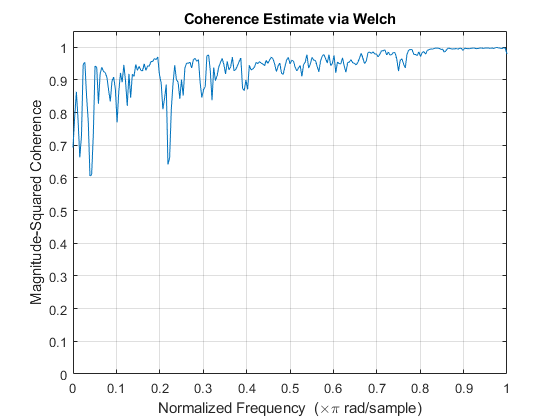

noise = 0.2;
y = filter(b, a, x);
y = y + noise*randn(N, 1);

% Compute and plot the coherence estimate
mscohere(y, x);
ylim([0, 1.05]);

#### High-pass filter with noise at the input

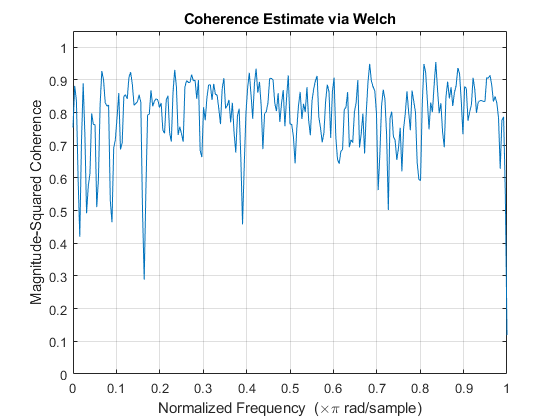

noise = 0.5;
y = filter(b, a, x + noise*randn(N, 1));
mscohere(y, x);
ylim([0, 1.05]);

The additional noise is also being filtered so we have equal amount.

#### Nonlinear filter

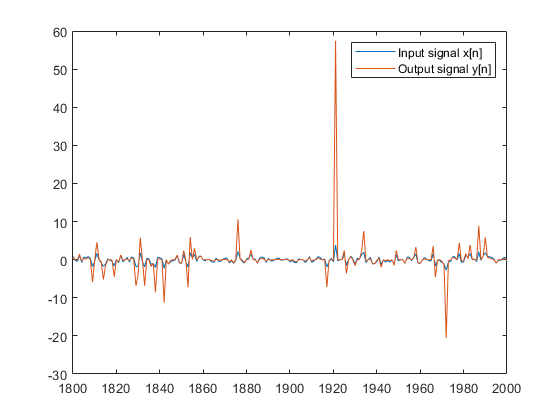

% Take each sample and cube it
y = x.^3; 
plot(n, x(n), n, y(n));
legend('Input signal x[n]', 'Output signal y[n]')

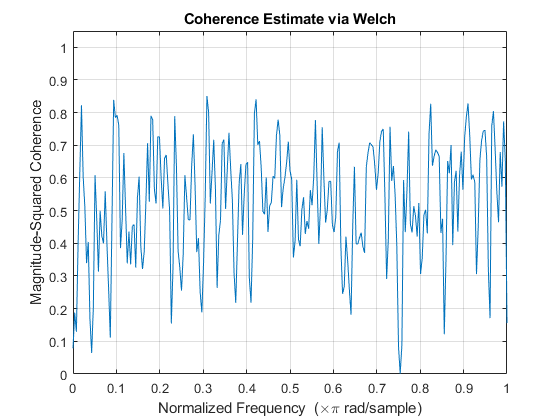

mscohere(y, x);
ylim([0, 1.05]);

The coherence is all over the place. 

***Lesson:*** Since the coherence function measures how close a system is linear, we don't know whether a low coherence is due to noise or a non-linear filter.

In practice, the coherence function is close to 1. The difference $1-\mathrm{mscohere}\left(y,x\right)$ tells us how well we can remove noise.

#### Nonlinear filter via clipping

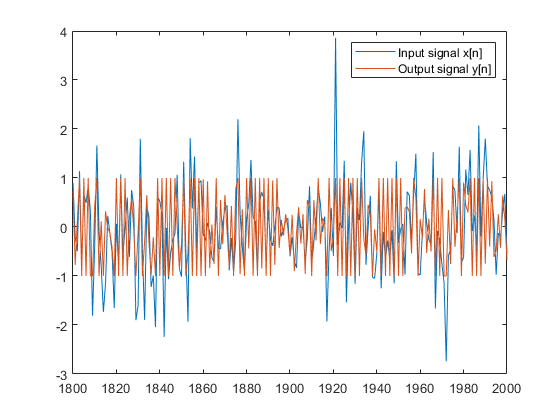

% Non-linear filter via clipping
y = filter(b, a, x);
for k=1:N
    if y(k)>1
        y(k)=1;
    end
    if y(k)<-1
        y(k)=-1;
    end
end
plot(n, x(n), n, y(n));
legend('Input signal x[n]', 'Output signal y[n]')

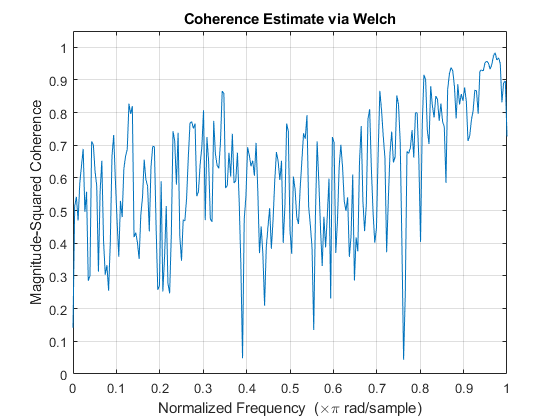

mscohere(y, x);
ylim([0, 1.05]);

We see more coherence in the high frequencies than the low frequencies. Research why? 

#### Comb Filter

Let us defined a comb filter which has the difference equation:


$$y\left\lbrack n\right\rbrack =b_0 x\left\lbrack n\right\rbrack +b_M x\left\lbrack n-M\right\rbrack$$


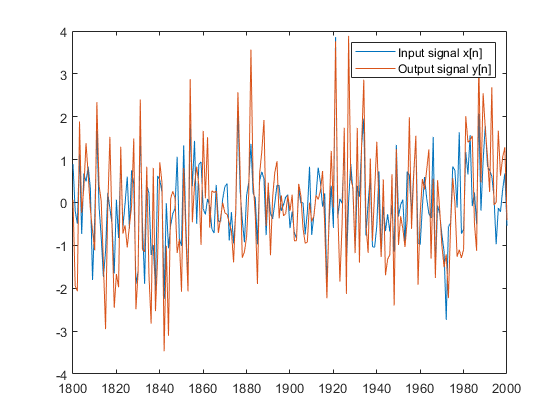

% Define a comb filter
b = [1 0 0 0 0 0 1];
a = 1;
y = filter(b, a, x);
plot(n, x(n), n, y(n));
legend('Input signal x[n]', 'Output signal y[n]')

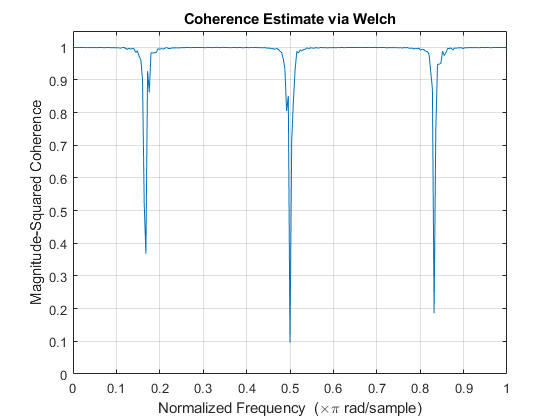

% Compute and plot the coherence estimate
mscohere(y, x);
ylim([0, 1.05]);

Notice that the coherence function dips at certain frequencies. This is because the comb filter removes certain frequency components of the input signal. Thefore, there is no coherence between the input signal and the output signal at those specific frequencies since the output signal does not contain these filtered frequencies.

The filter has 6 zeros on the unit circle, which means that it is removing 6/2=3 frequency components:

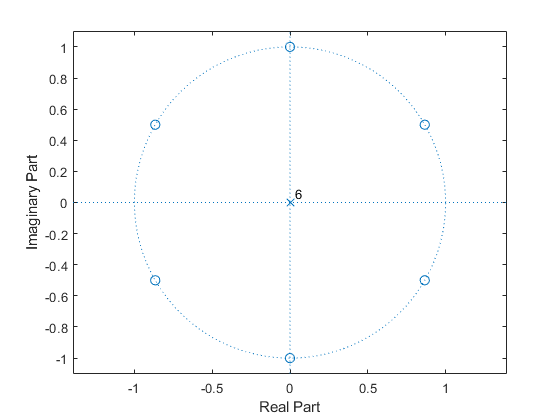

zplane(b, a)

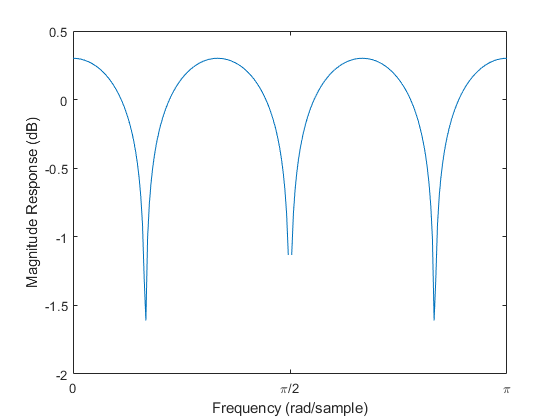

% Plot the magnitude response to see which frequency
% components are being attenuated
[H, w] = freqz(b, a, 'whole');
plot(w, log10(abs(H)));
set(gca,'XTick',0:pi/2:2*pi) 
set(gca,'XTickLabel',{'0','\pi/2','\pi','3\pi/2','2\pi'})
xlabel('Frequency (rad/sample)')
ylabel('Magnitude Response (dB)')
xlim([0, pi]);

## Properties of White Noise

White noise is important for random signal modelling. 

`INSIGHT`*:* we can use white noise to find the impulse response of a system because the autocorrelation of white noise is the same the delta signal.

Suppose we have a random process that produces perfect random noise. 

Let $w\left(n\right)$ be a random signal from this process.

The** expected value** of the signal is zero because there are no patterns in white noise:

    
$$E\left\lbrack w\left(n\right)\right\rbrack =0$$


The **autocorrelation of white noise** generates one peak at $\ell =0$ because that is the only time when there is any correlation of the signal. One peak at $\ell =0$ can be modelled by delta signal:

        
$$r_{\textrm{ww}} \left(\ell \right)=E\left\lbrack w\left(n\right)w\left(n-\ell \right)\right\rbrack =\sigma_w^2 \delta \left(\ell \right)$$


where $\sigma_w^2$ is the variance of the signal which can be computed as follow:

        $\begin{array}{l}
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack -E{\left\lbrack w\left(n\right)\right\rbrack }^2 \\
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack -0\\
\sigma_w^2 =E\left\lbrack w^2 \left(n\right)\right\rbrack 
\end{array}$     (by definition $E\left\lbrack w\left(n\right)\right\rbrack =0$)

The **power spectral density of white noise** is:

        
$$S_w \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } r_{\mathrm{ww}} \left(\ell \right)e^{-j\omega \ell }$$


        
$$S_w \left(\omega \right)=\sum_{\ell =-\infty }^{\infty } \sigma_w^2 \delta \left(\ell \right)e^{-j\omega \ell }$$


All terms where $\ell \not= 0$ become zero so we left with one term when $\ell =0$

        
$$S_w \left(\omega \right)=\sigma_w^2 \delta \left(0\right)e^{-j\omega \cdot 0}$$


        
$$S_w \left(\omega \right)=\sigma_w^2 \cdot 1\cdot 1$$


        
$$S_w \left(\omega \right)=\sigma_w^2$$


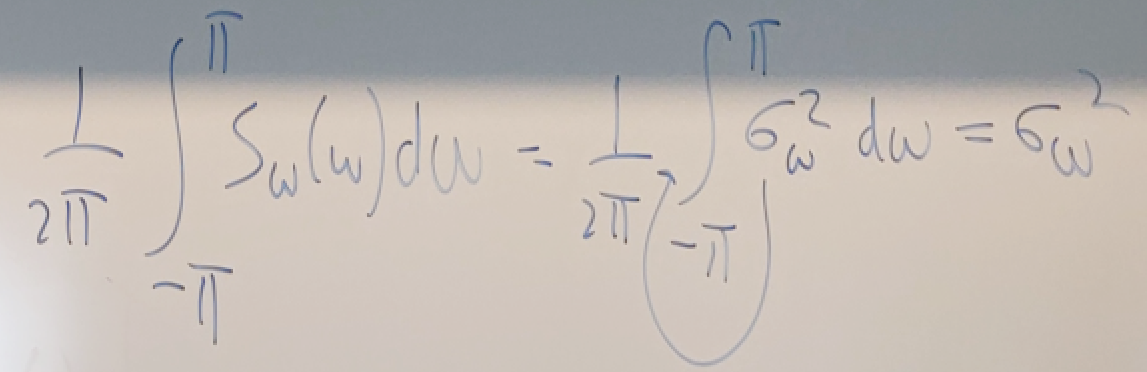

### Quiz: white noise cubed

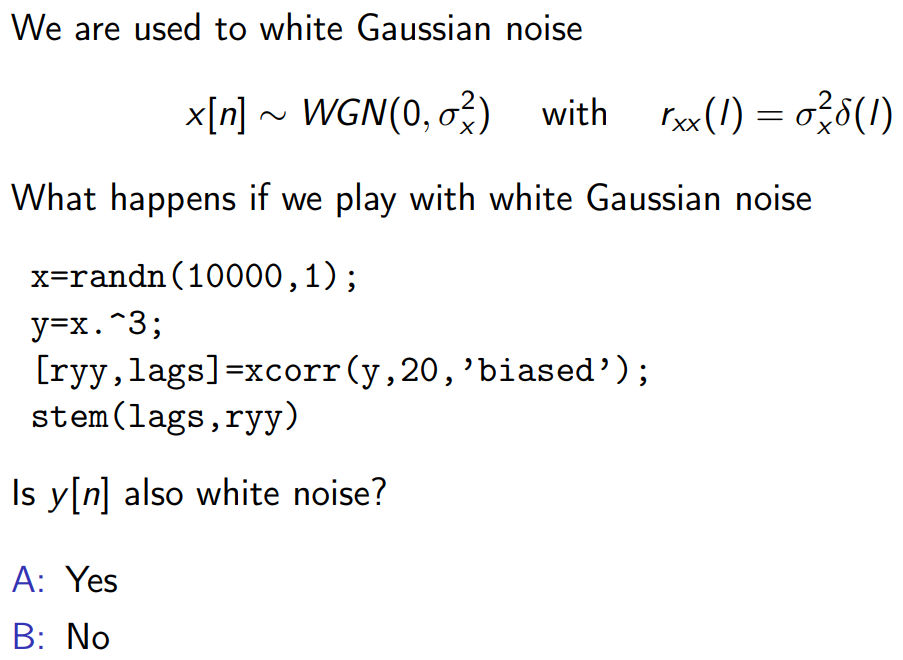

So the question is this: suppose we have a white noise signal $x\left(n\right)$. If we take each element of this signal and cube it, would the resulting signal also be white noise?

The answer is yes! The output is also white noise because we are not introducing any correlation between different samples. 

Let us prove it in MATLAB.

If we plot the autocorrelation of white noise, we should observe a signal similar to delta signal with amplitude of $\sigma_x^2$ because:

    if $x\left(n\right)~\mathrm{WGN}\left(0,\sigma_x^2 \right)$ then $r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)$

First, we plot $r_{\mathrm{xx}} \left(\ell \right)$

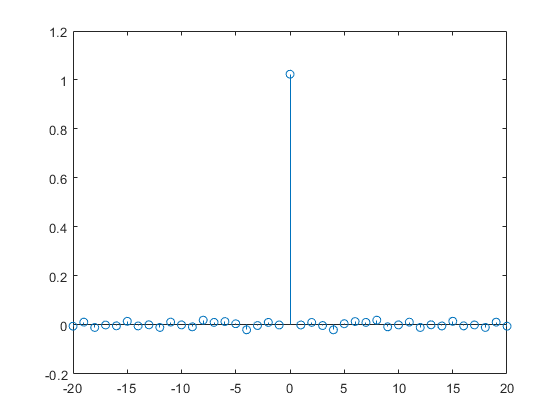

N = 10000;
n = [1:N];
x = wgn(N,1,0);

[r_xx, lags] = xcorr(x, 20, 'biased');
stem(lags, r_xx);

This looks like what have expected.

Now, let us plot the autocorrelation of $y\left(n\right)=x^3 \left(n\right)$

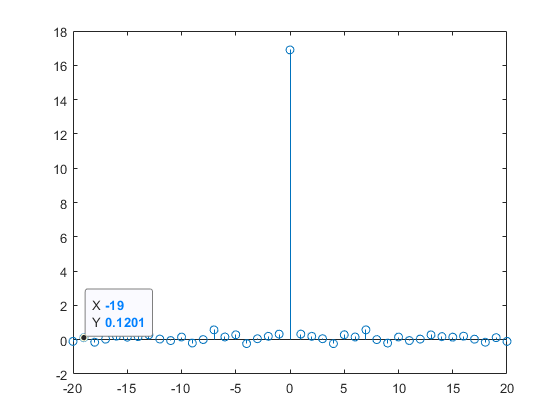

y = x.^3;
[r_yy, lags] = xcorr(y, 20, 'biased');
stem(lags, r_yy);

This proves that the answer to the quiz is Yes!

`INSIGHT`***: ***Noise does not necessarily have to be Gaussian in order to be white. White noise can have any probability density function. Noise is said to be white when there is no correlation between samples.

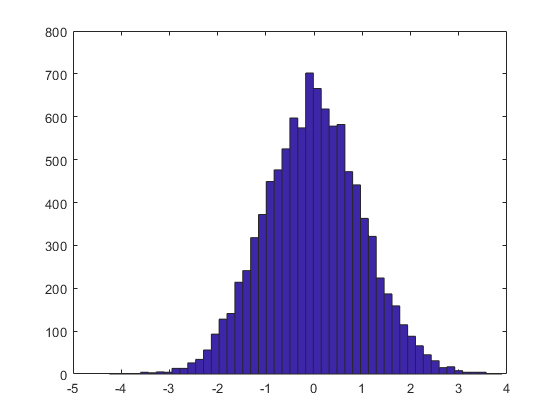

hist(x, 50)

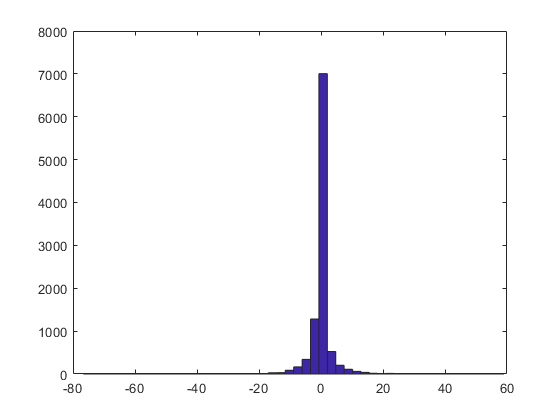

hist(y, 50)

### Quiz: decide whether a sequence is white noise

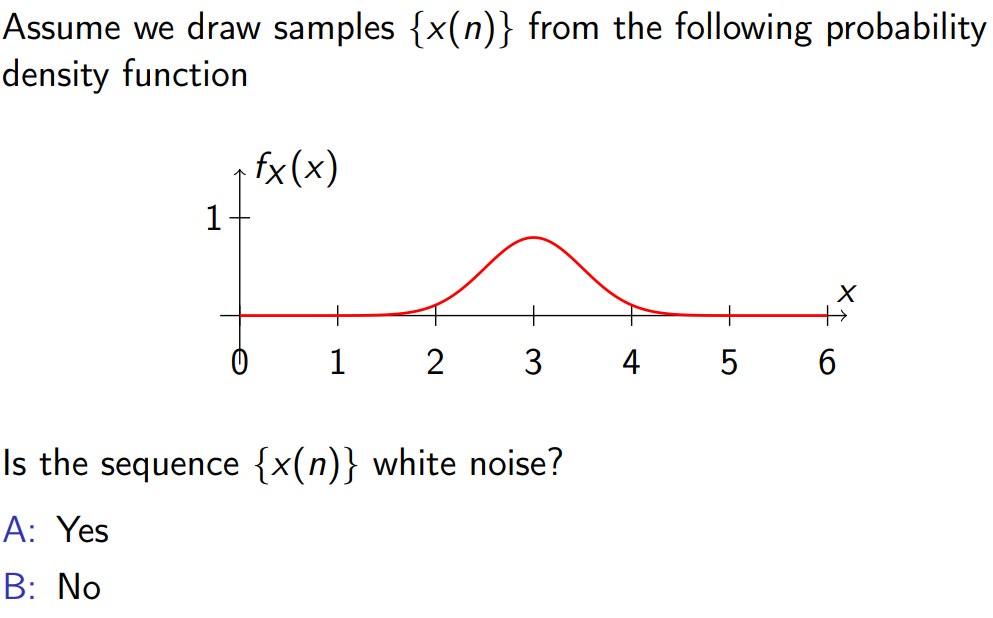

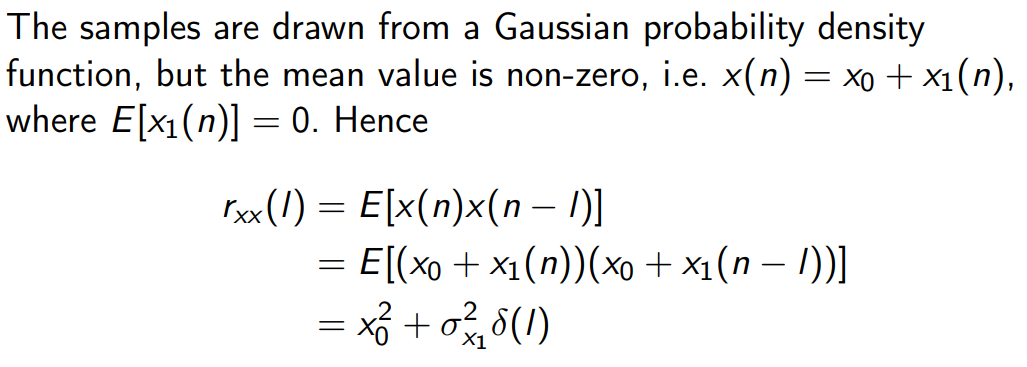

## Signal Modelling

Signal modelling is about gaining some understanding of certain signals so we can model them. We do not need to have a full suite of samples but we want to understand from a statistical perspective.

White noise a building blocks that we can use.

Signal modelling is about taking some unknown signal $y\left(n\right)$ and coming up with an LTI system that generates $y\left(n\right)$ given some white noise input.

All the correlation that was between samples before are stored in the filter coefficients. This becomes a model of our signal. If we know the filter, we know the signal. The samples of the signal will not be the same but the signal will have the same statistical properties.

We cannot generate the exact same $y\left(n\right)$ using different white noise inputs. Instead we generate signals with the **same statistical properties**.

### Regular processes

A regular process is just a minimum-phase LTI system given by the difference equation:

        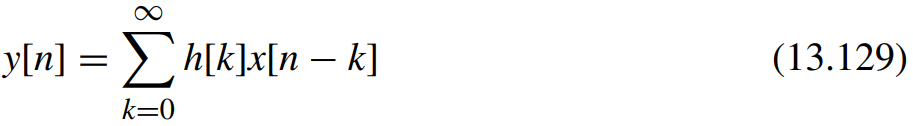

This is just a FIR filter with infinitely many coefficients.

The filter $h\left\lbrack n\right\rbrack$ is known as a ***synthesis*** or ***colouring*** filter.

Since the LTI system is minimum-phase, it is causal, stable and therefore also invertible.

        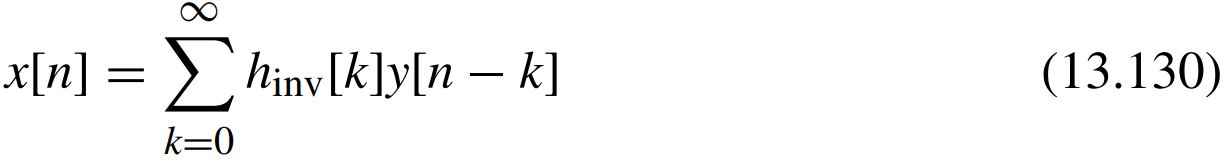

This system is known as an ***analysis*** or ***whitening*** filter.

If feed this minimum-phase LTI system a white noise signal, we can compute the autocorrelation and PSD of the resulting process:

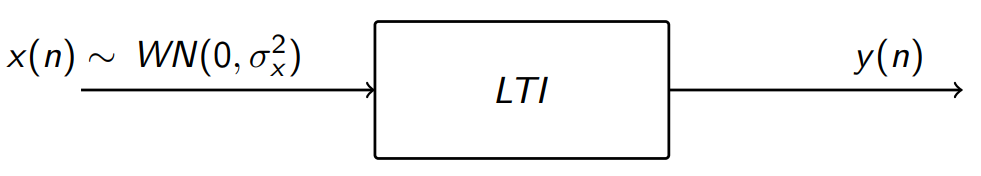

The autocorrelation of the input signal (white noise) is:

        $r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)$,     where $\sigma_x^2 =E\left\lbrack x^2 \left(n\right)\right\rbrack$ is the variance

The power spectral density of the input signal is:

        
$$S_{\mathrm{xx}} \left(\omega \right)=\sigma_x^2$$


The autocorrelation of the output signal is:

        
$$r_{\mathrm{yy}} \left(\ell \right)=\sigma_x^2 \;r_{\mathrm{hh}} \left(\ell \right)$$


The power spectral density of the output signal is power transfer function of the LTI system:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 \;{\left|H\left(e^{j\omega } \right)\right|}^2$$


Finding the synthesis filter $h\left\lbrack m\right\rbrack$ from the autocorrelation or PSD is known as ***spectral factorization***. This is essentially what signal modelling is about; taking some unknown signal $y\left\lbrack n\right\rbrack$ and coming up with a minimum-phase LTI system that generates $y\left(n\right)$ given some white noise input.

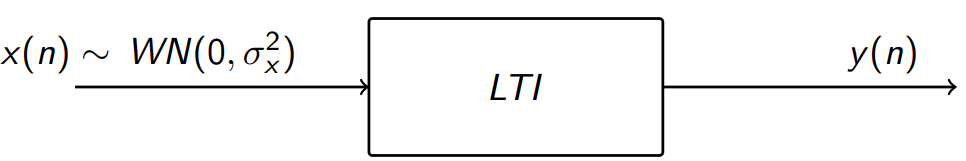

### Paley-Wiener condition

A process is regular if its PSD satisfies the Paley–Wiener condition:

        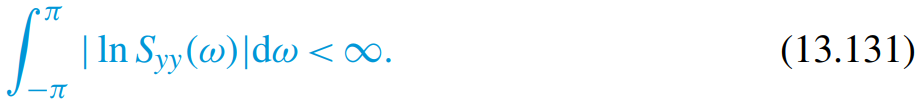

There are two kind of signals that cannot be modelled by an LTI system driven by white noise:

- signal with line spectra e.g. sinusoids $\mathrm{cos}\left(\omega \right)$

- bandwidth limited spectra

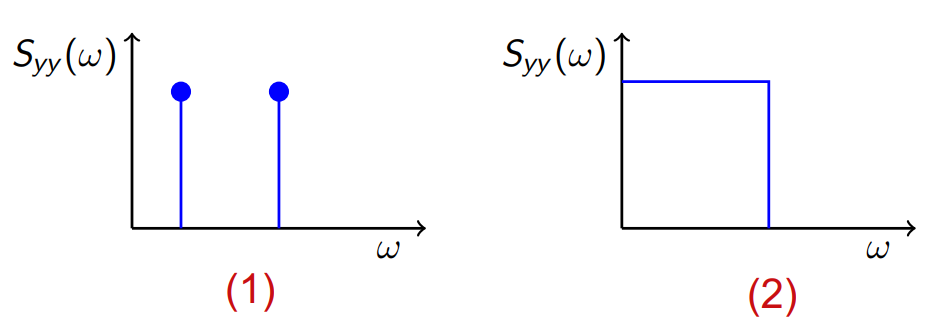

We cannot model these types of signals because it does not fulfill the Paley-Wiener condition:

        

#### Modelling signals with line spectra

Signals with line spectra are easy to model. 

Suppose we want to model following signal:

        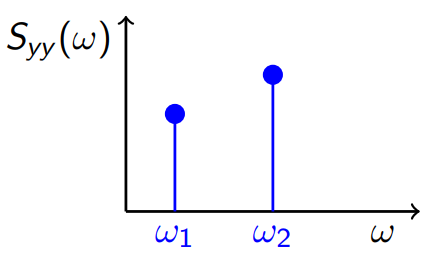

We can just use a **harmonic process** to model the signal:

        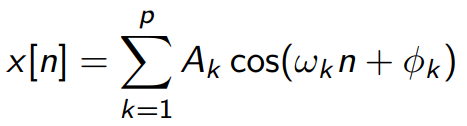

where

- 
$$\omega_k \not= 0$$


- $p$ is a constant denoting the number of frequency components

- $A_1 ,\cdots ,A_p$ are constants denoting amplitudes

- $\omega_1 ,\cdots ,\omega_p$ are constants denoting frequencies

- $\phi_1 ,\cdots ,\phi_p$ are pairwise independent random variables uniformly distributed in the interval $\left(0,2\pi \right)$

This model has $3p$ parameters $A_k ,\omega_k$ and $\phi_k$ that we need to estimate. We can find these parameters using the least-squares.

The harmonic process is wide-sense stationary with mean value zero:

        
$$E\left\lbrack x\left(n\right)\right\rbrack =0$$


The autocorrelation of the harmonic process is:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\frac{1}{2}\sum_{k=1}^p A_k^2 \;\mathrm{cos}\left(\omega_k \ell \right)$$


Take the Fourier Transform, we get the power spectral density:

        
$$S_{\mathrm{xx}} \left(\omega \right)=\sum_{k=1}^p 2\pi \frac{A_k^2 }{4}\left\lbrack \delta \left(\omega -\omega_k \right)+\delta \left(\omega +\omega_k \right)\right\rbrack$$


#### Modelling signals with bandwidth limited spectra

If we want to compute a filter with the brick-wall shape (2), we need an infinitely long non-causal filter. However, we said that we only wanted minimum-phase filters i.e. causal and stable filter. Therefore, this is not going to work.

## Wold decomposition

The Wold decomposition says: *any stationary discrete-time process can be expressed as the sum of two ****uncorrelated**** processes, one regular process and one harmonic process.*

Now, let us go back to the regular process and introduce the ARMA(p, q) model.

## ARMA(p, q) model

An ARMA(p,q) process is defined by the difference equation:

        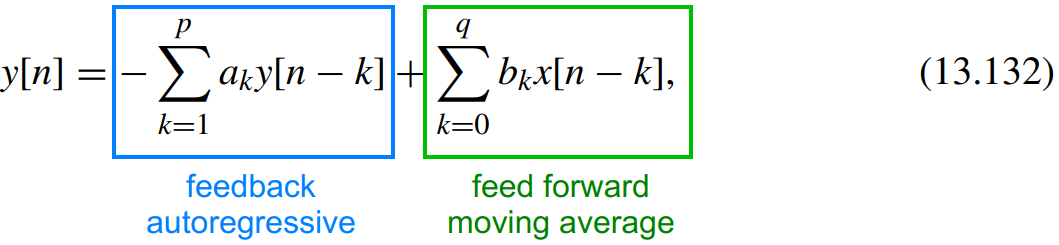

where $x\left\lbrack n\right\rbrack ~\mathrm{WN}\left(0,\sigma_x^2 \right)$

This is just a standard IIR filter.

### Finding ARMA(p,q) Model Parameters

How can find the model coefficients $\left\lbrace a_k ,b_k \right\rbrace$ given an output signal $y\left(n\right)$?

The autocorrelation can be computed numerically in MATLAB given an output signal.

We can also derive an analytical expression of the autocorrelation of the output signal:

        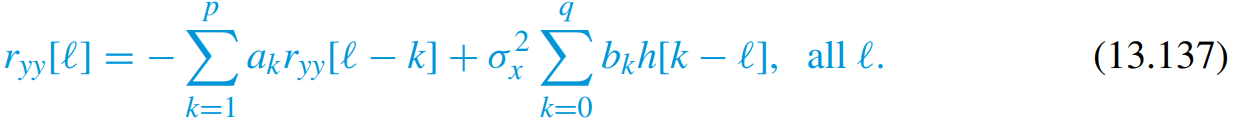

However, we have an issue with this expression. The impulse response $h\left\lbrack n\right\rbrack$ is actually some function of the coefficients $\left\lbrace a_k ,b_k \right\rbrace$.  The issue is that this function is a non-linear. So solving the analytical expression becomes troublesome.

However, if we get rid of the second term by setting $q=0$, the relation becomes linear and we have an AR(p) process:

        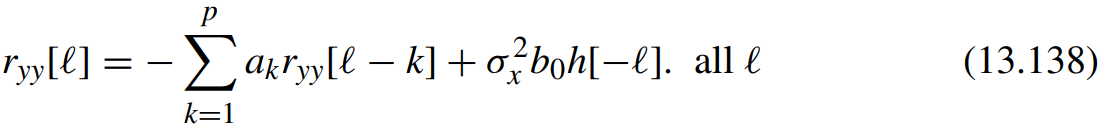

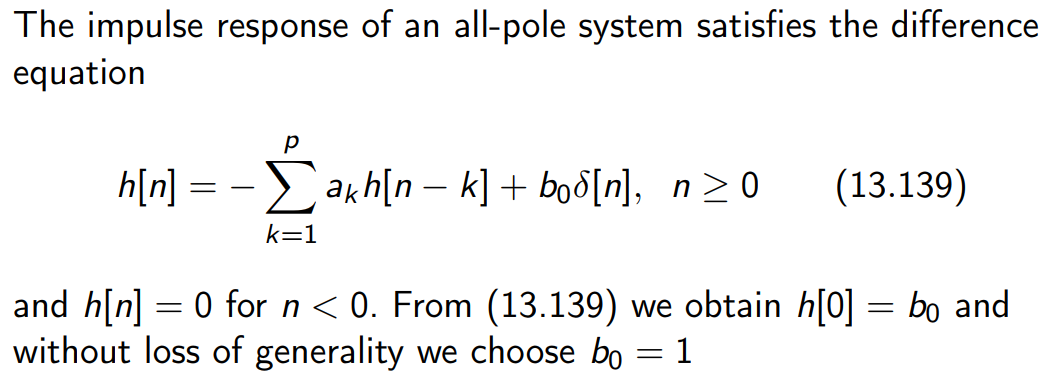

***Quiz:*** why can we choose to set $b_0 =1$?

Well, we are sending a WN signal into an LTI system. There is a certain about of power in the white noise. The $b_0$ is a constant used to amplify the power. It is difficult to distinguish whether the power originates from the power in white noise or the power in the gain. The power appears as one quantity. In this case, we fix one of the filter coefficients and we say that any power that we observe is in the white noise. 

        

We only consider positive lags $\ell >0$ because $h\left(\ell \right)=0$ for $\ell <0$ i.e., the impulse response does not exists of negative times because it is a causal system.

        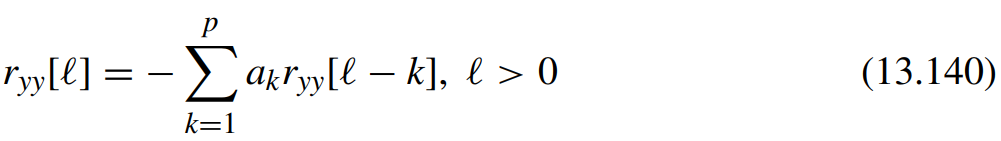

The ARMA(p, q) model consists of two submodels. Normally, we do not use the full ARMA model but only one of the submodels.

### AR(q) models

AR(p) model is given by:

        
$$y\left(n\right)=-\sum_{k=1}^p \left\lbrack a_k \;y\left(n-k\right)\right\rbrack +b_0 x\left(n\right)$$


The autocorrelation of AR(q) model was derived in Eq. 13.141 as:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model. Given an output signal $y\left(n\right)$, we can compute the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

For example, if we want to model second-order AR model,$p=2$ we get two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form:

        
$$\left\lbrack \begin{array}{cc}
r_{\mathrm{yy}} \left(0\right) & r_{\mathrm{yy}} \left(-1\right)\\
r_{\mathrm{yy}} \left(1\right) & r_{\mathrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\mathrm{yy}} \left(1\right)\\
r_{\mathrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


### MA(q) models

MA(q) model is given by:

        
$$y\left(n\right)=\sum_{k=0}^q b_k \;x\left(n-k\right)$$


This is the ARMA(p, q) model where the feedback part is excluded i.e., all values of $a_k$ is set to zero.

### Quiz: determine kind of model based on the inpulse response

The impulse response for a specific ARMA(*p,**q*) model is shown below.

What kind of model is shown?

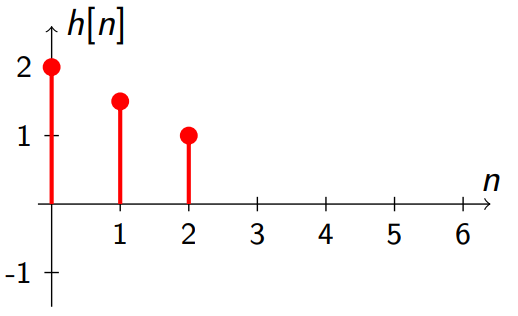

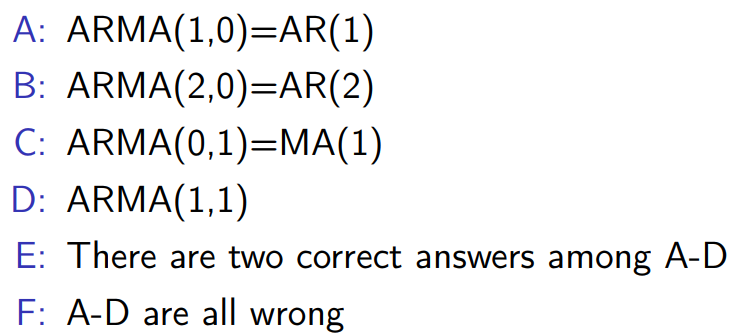

The correct answer is F.

The autoregressive part of the ARMA(p,q) model has infinite impulse response. What we see in the figure is finite impulse response with three elements. Therefore, it must be an MA(q) model.

Since the figure shows three filter coefficients, the system must be an MA(2) process.

If the figure indicated infinite filter coefficients, we could not have determined the order of the model. In this case, it would be either an autoregressive model or a high-order MA(q) model.

### Quiz: is the comb filter an MA(1) proces?

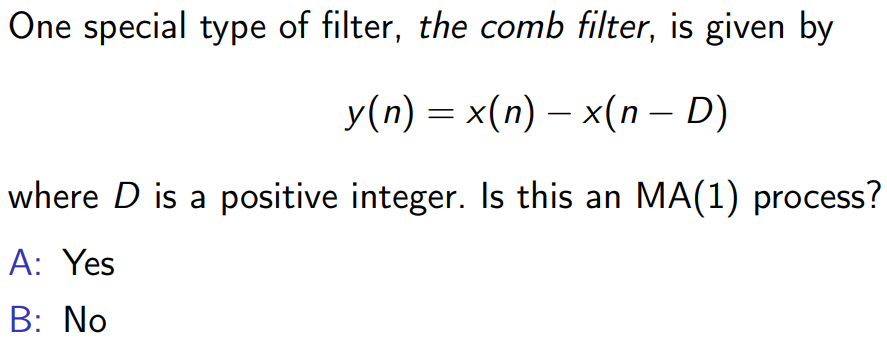

The answer is no!